# **Question 4**

clc; clear;

load 402123100


y = id.y;
u = id.u;

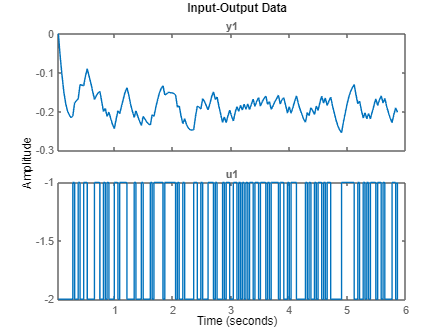

N = length(y);

y_val = val.y;
u_val = val.u;

figure()
plot(id)
hold on

na = 2;
nb = 1;

U = arx_U_builder(na,nb,u,y);
disp("U = ")

U = 


disp(U(1:10,:))

         0         0   -2.0000         0
   -0.0006         0   -2.0000   -2.0000
    0.0582   -0.0006   -2.0000   -2.0000
    0.1070    0.0582   -2.0000   -2.0000
    0.1489    0.1070   -2.0000   -2.0000
    0.1783    0.1489   -2.0000   -2.0000
    0.1983    0.1783   -2.0000   -2.0000
    0.2084    0.1983   -2.0000   -2.0000
    0.2162    0.2084   -1.0000   -2.0000
    0.2113    0.2162   -2.0000   -1.0000




theta_hat = inv(U'*U)*U'*y;
y_hat = U*theta_hat;

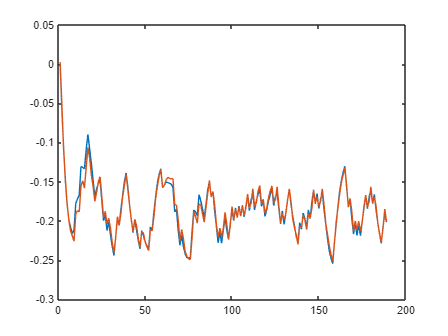

figure()
plot(y,'-')
hold on
plot(y_hat, '-')


disp("----------------Model Evaluation Report-------------------")

----------------Model Evaluation Report-------------------



SST = sum((y-mean(y)).^2);
SSE = sum((y-y_hat).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('------> SSE : %.7f \n', SSE);

------> SSE : 0.0071355 


fprintf('------> MSE : %.7f \n', MSE);

------> MSE : 0.0000378 


fprintf('------> R2  : %.7f \n', R2);

------> R2  : 0.9678453 



disp("===========================================================")

### Bonus Question

model = arx([y_val,u_val], [na nb 1]);

% compare([y_val, u_val], model)

y_pred = lsim(model, u_val);

disp("----------------Model Evaluation Report-------------------")

----------------Model Evaluation Report-------------------



SST = sum((y_val-mean(y_val)).^2);
SSE = sum((y_val-y_pred).^2);

R2 = 1 - (SSE/SST);

MSE = SSE/N;

fprintf('------> SSE : %.7f \n', SSE);

------> SSE : 0.0640527 


fprintf('------> MSE : %.7f \n', MSE);

------> MSE : 0.0003389 


fprintf('------> R2  : %.7f \n', R2);

------> R2  : 0.9107713 



disp("===========================================================")

`arx` command provides a model estimation with 0.91. However, R2 value is higher in the hand-written algorithm of ours. Note that both of the are gretaer than 0.9 and they are proper.